# NeuroTech 2021 ANOVA Exploration

## Basic Information and Example of ANOVA

**Sam Coleman**

## What is ANOVA?

- Analysis of Variance (ANOVA) “is a collection of statistical models and their associated estimation procedures (such as the "variation" among and between groups) used to analyze the differences among means”

- Can help to figure out if survey or experiment results are significant - helps to figure out if you need to reject the null hypothesis or accept the alternate hypothesis

- Generalizes a t-test beyond 2 means

## Types of Appropiate Data

- Dependent variable: continuous (interval or ratio)

- Independent variable: categorical (nominal or ordinal)

## Assumptions and Requirements

- Independence of observations.

- The dependent variable is normally distributed in each group that is being compared in the one-way ANOVA

- Can tolerate non normal data with only small effect on type 1 error

- There is homogeneity of variances. This means that the population variances in each group are equal.

## Mathematical Overview

**Broad overview of what ANOVA is doing:**

- Find variance between the groups

- Find variance within the groups

- F = between_groups / within_groups

- Larger F is, more likely the groups have different means and therefore reject the Null Hypothesis

**Standard for Reporting the Results **

- Show the degerees of freedom: F(b,w) = proportion

- b: degrees of freedom for variance between groups: number of groups - 1

- w: degrees of freedom for variance within groups: total number of observations - number of groups

## Measure of Effect Size

- Eta squared

## Sources

- [https://en.wikipedia.org/wiki/Analysis_of_variance](https://en.wikipedia.org/wiki/Analysis_of_variance)

- [https://www.statisticshowto.com/probability-and-statistics/hypothesis-testing/anova/](https://www.statisticshowto.com/probability-and-statistics/hypothesis-testing/anova/)

- [https://statistics.laerd.com/statistical-guides/one-way-anova-statistical-guide-2.php](https://statistics.laerd.com/statistical-guides/one-way-anova-statistical-guide-2.php)

- [https://www.statisticssolutions.com/manova-analysis-anova/](https://www.statisticssolutions.com/manova-analysis-anova/)

## Example

Data set source: [https://college.cengage.com/mathematics/brase/understandable_statistics/7e/students/datasets/owan/frames/owan04.html](https://college.cengage.com/mathematics/brase/understandable_statistics/7e/students/datasets/owan/frames/owan04.html)

**The following data represent business startup costs (thousands of dollars) for shops.**

 X1 = startup costs for pizza 

 X2 = startup costs for baker/donuts

 X3 = startup costs for shoe stores

 X4 = startup costs for gift shops

 X5 = startup costs for pet stores

**Null Hypothesis (**$H_0$**)**: The startup costs for all business are the same

data = readtable("anovaData.csv") %import data

data = 16×5 table
    X1     X2     X3     X4     X5 
    ___    ___    ___    ___    ___

     80    150     48    100     25
    125     40     35     96     80
     35    120     95     35     30
     58     75     45     99     35
    110    160     75     75     30
    140     60    115    150     28
     97     45     42     45     20
     50    100     78    100     75
     65     86     65    120     48
     79     87    125     50     20
     35     90    NaN    NaN     50
     85    NaN    NaN    NaN     75
    120    NaN    NaN    NaN     55
    NaN    NaN    NaN    NaN     60
    NaN    NaN    NaN    NaN     85
    NaN    NaN    NaN    NaN    110


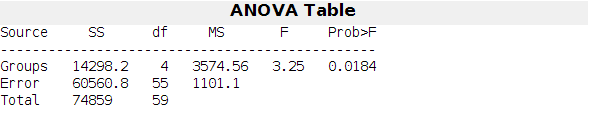

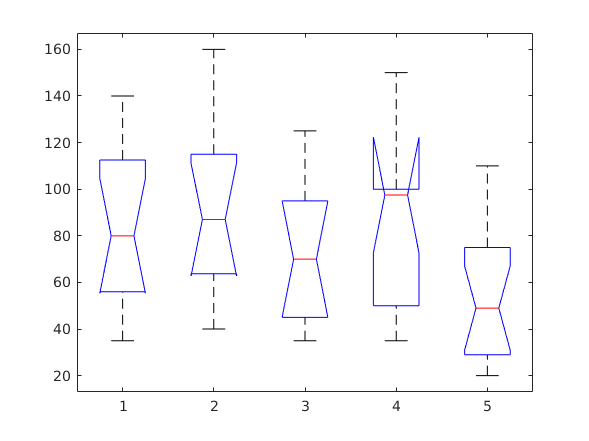

p = 0.0184


x_vals = [data.X1, data.X2, data.X3, data.X4, data.X5]; %put data into matrix 
p = anova1(x_vals) %use MATLAB ANOVA function

Looking at the anova table, we see F(4, 55) = 3.25. Since the F value is larger, we will reject the Null hypothesis.